****Part A)****

A particle P is launched from point A with the initial conditions defined below

%initial velocity (m/s)
v_in = 70;
theta = 35;
%degree to radians
theta = theta * pi / 180

theta = 0.6109

vx_in = v_in * cos(theta)

vx_in = 57.3406

vy_in = v_in * sin(theta)

vy_in = 40.1504



%aerodynamic drag constant(1/m)
k = 4.0 * 10^(-3);

The acceleration due to aerodynamic drag is 

%aD
syms V(t) Vx(t) Vy(t)
V(t) = sqrt(Vx(t)^2 + Vy(t)^2);
a_drag = -k*V(t)^2;
ax_drag = simplify(a_drag * Vx(t) / V(t));
ay_drag = simplify(a_drag * (Vy(t) / V(t)));

First we solve the problem in the y direction. Note that there's a downward (negative) gravitational acceleration which must be included in the calculations.

G = -9.81;

%total acceleration in y direction
syms a_y(t)
a_y(t) = ay_drag + G

$$a\_y(t) = -\frac{\mathrm{Vy}\left(t\right)\,\sqrt{{\mathrm{Vx}\left(t\right)}^{2}+{\mathrm{Vy}\left(t\right)}^{2}}}{250}-\frac{981}{100}$$

%total acceleration in x direction
syms a_x(t)
a_x(t) = simplify(ax_drag)

$$a\_x(t) = -\frac{\mathrm{Vx}\left(t\right)\,\sqrt{{\mathrm{Vx}\left(t\right)}^{2}+{\mathrm{Vy}\left(t\right)}^{2}}}{250}$$


%Defining initial condiyions matrix required for solving the differential equation via ode45
[t,m] = ode45(@f,[0 11], [0 vx_in 0  vy_in]);

h_index = find(abs(m(:,3) - 0)<2);
h_index(end);
Range_with_drag = m(h_index(end),1)

Range_with_drag = 217.8889

- trajectory without air drag

%solving the differential equation ay = g = dy2/dt
syms y(t) t y_nodrag(t)
Dy = diff(y,t);
ode = diff(y,t,2) == G;
cond1 = y(0) == 0;
cond2 = Dy(0) == vy_in;
conds = [cond1 cond2];
y_nodrag(t) = simplify(dsolve(ode, conds))

$$y\_nodrag(t) = \frac{5650659492229211\,t}{140737488355328}-\frac{981\,t^{2}}{200}$$


eqn = y_nodrag(t) == 0;
t2 = eval(solve(eqn, t));
t2 = t2(2);

% motion equation for x direction
syms x_nodrag(t) t
x_nodrag(t) = vx_in * t;
Range_noDrag = eval(x_nodrag(t2))

Range_noDrag = 469.3674

**** Part B) Ploting the results ****

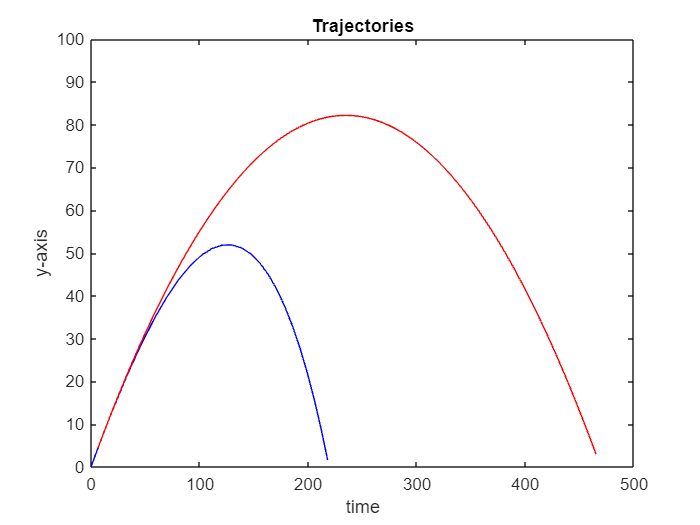

%y and x ( with air drag):
y = m(:,3);
x = m(:,1);

%y and x (without air drag)
time = linspace(0,11,100);
x_nd = x_nodrag(time);
y_nd = y_nodrag(time);

%ploting
plot(x(y>0), y(y>0),'b', x_nd(y_nd>0), y_nd(y_nd>0), 'r');
axis([0 500 0 100]);
title ("Trajectories");
xlabel("time");
ylabel("y-axis");

**** Part C) Obstacles****

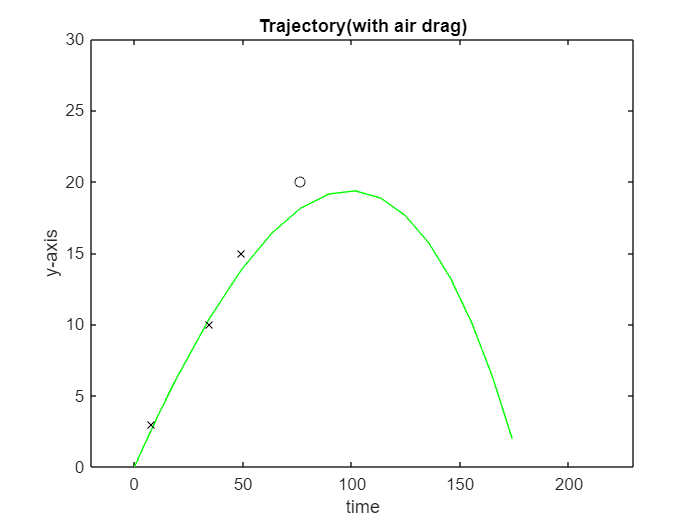

b=19;
vxandy = V0(b, v_in);
vx0 =vxandy(1);
vy0 =vxandy(2);
plot_trajectory(vx0, vy0);

Defined function for ode45 and part C

function dydt = f(t,m)
     v = sqrt(m(2)^2 + m(4)^2);
     g = -9.81;
     k = 4.0 * 10^(-3);
     dydt = [m(2);-1*m(2)*v*k; m(4); -1*m(4)*v*k + g];
end

function v = V0(b, vin)
    vx0 = vin * cos(b * pi / 180);
    vy0 = vin * sin(b * pi / 180);
    v = [vx0;vy0];
end

function hit = game_rules(y_60, y_40, y_20)
    %goal at x = 80     obstacle 3 at gx - 20   obstacle 2 at gx - 40   obstacle 1 at gx - 60
    obs3 = 15;
    obs2 = 10;
    obs1 = 3;
    
    
    hit = 1;
    if (abs(y_60 - obs3) > 10)
        hit = 0;
    elseif (abs(y_40 - obs2) > 10)
        hit = 0;
    elseif (abs(y_20 - obs1) > 10)
        hit = 0;
    end
end

function range = plot_trajectory(vx0, vy0)
    [t,m] = ode45(@f,[0 11], [0 vx0 0  vy0]);
    
    %obs1
    h_goal = find(abs(m(:,3) - 20) < 2);
    if (size(h_goal) > 0)
        goalx = m(h_goal(1),1);
    else
        goalx = 60;
    end
    
   
    if(goalx > 61)
        h_obs3 = find(abs(20 - goalx + m(:,1)) < 10);
        h_obs2 = find(abs(40 - goalx + m(:,1)) < 10);
        h_obs1 = find(abs(60 - goalx + m(:,1)) < 10);

        obs1x = m(h_obs1(1),1);
        obs2x = m(h_obs2(1),1);
        obs3x = m(h_obs3(1),1);
        if (game_rules( m(h_obs3(1),3), m(h_obs2(1),3), m(h_obs1(1),3)) )
            color = 'g';
        else
            color = 'r';
        end
    else
            color = 'r';
            obs1x = goalx - 60;
            obs2x = goalx - 40;
            obs3x = goalx - 20;
    end

    %y and x ( with air drag):
    y = m(:,3);
    x = m(:,1);
     
    %ploting
    plot(x(y>0), y(y>0),color, obs1x, 3 , 'black -x',obs2x, 10 , 'black -x',obs3x, 15 , 'black -x',goalx, 20 , 'black -o');
    axis([-20 230 0 30]);
    title ("Trajectory(with air drag)");
    xlabel("time");
    ylabel("y-axis");
end

